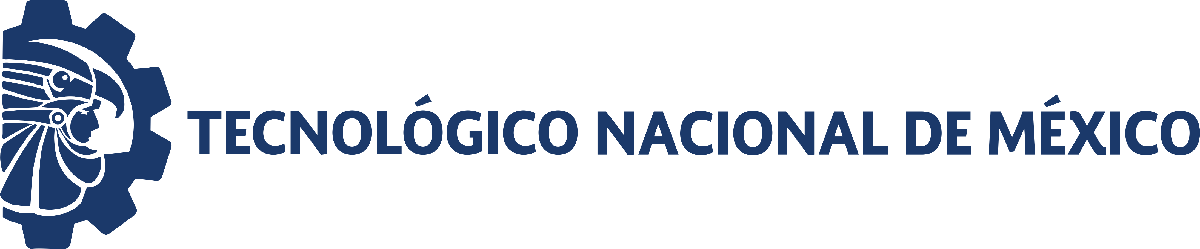                                 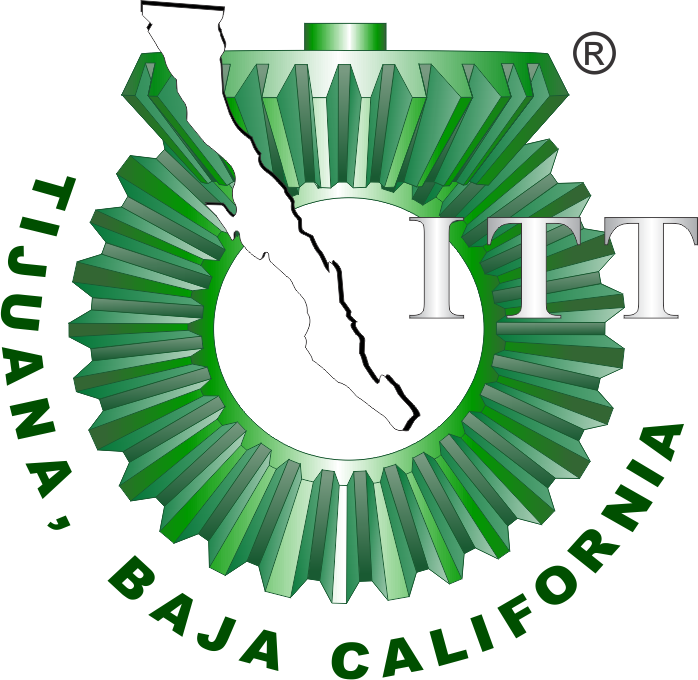

# Práctica 3: Modelado y control del sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

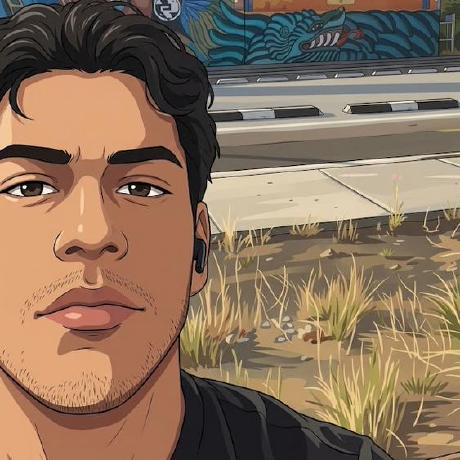

Nombre del alumno: Andrade Arellano Gael Sebastian

Número de control: 23212177

Correo institucional:** l212177@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Andrade23212177.slx')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';

## Respuesta hipotenso, normotenso e hipertenso

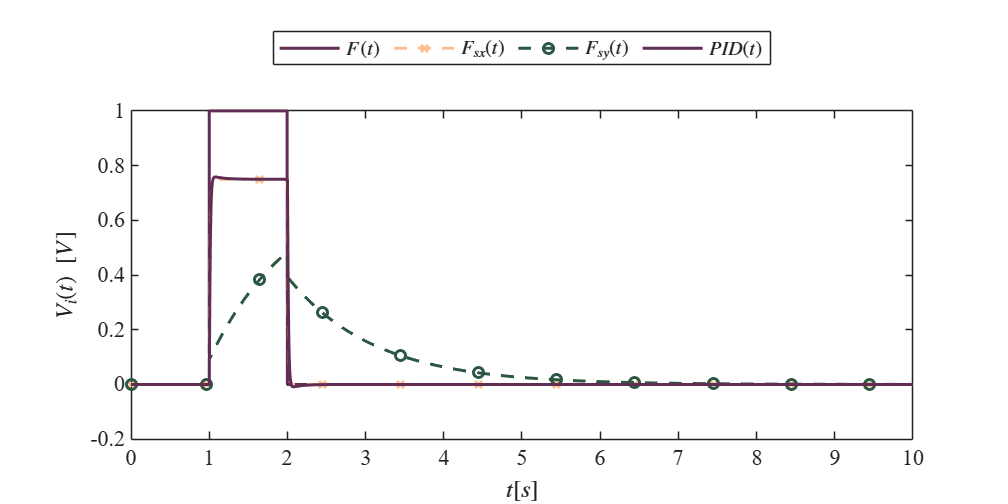

x = sim('Andrade23212177',parameters);
plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID, 'impulso unitario')

## Funcion: Respuestas de la simulacion

function plotsignals (t, PpL, PpN,PpH, PIDL, signal)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off; box on;
clr1 = [97,45,83]/255;
clr2 = [255,190,145]/255;
clr3 = [44,87,69]/255;
order = [clr1;clr2;clr3]; colororder(order)

if signal == 'impulso unitario'
    plot(t, PpL, '-', t, PpN, '--x', t, PpH, '--o',t, PIDL, ...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1e2:length(t));
    L = legend('$F(t)$', '$F_{sx}(t)$', '$F_{sy}(t)$', '$PID(t)$');
end     
set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
xlabel('$t[s]$','interpreter','latex')
ylabel('$V_i(t)\ [V]$','interpreter','latex')

xlim([0 10]); xticks(0:1:10)

if signal == "impulso unitario"
end

exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')

end